file = 230  ;

**ECG GRAPH:  **

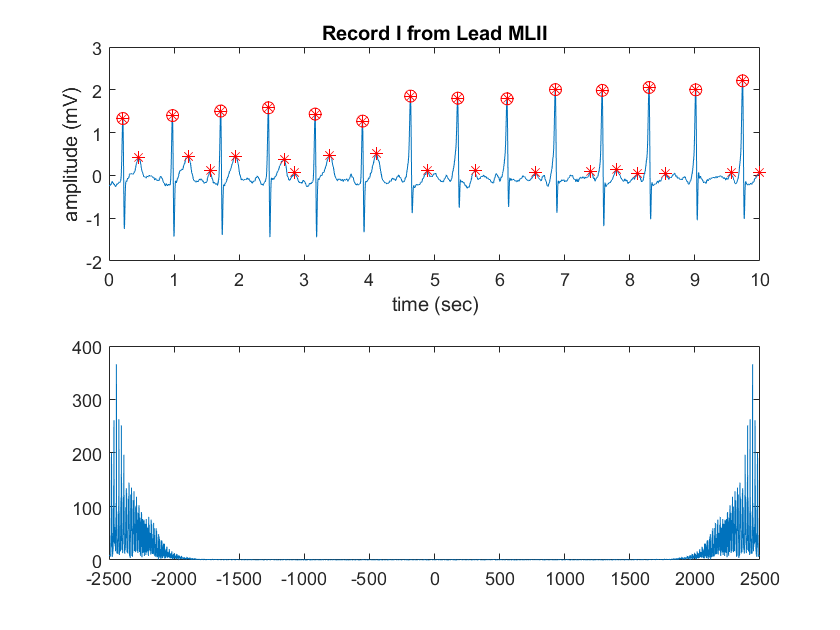

wfdb2mat(int2str(file));  % convert .dat file to .mat file
load([int2str(file), 'm.mat']);
[tm, signal, Fs, labels] = rdmat([int2str(file), 'm']);
signal = signal(:,1);

% filter    
signal = highpass(signal,1,360);

%% analysis
figure(1)
avg = mean(signal);
signal = signal-avg;

brady = []; tachy = []; pre = []; supra = [];
R_inversion = 0;
P_inversion = 0;
for i = 1:129
    T = tm(i*5000:(i+1)*5000); SIGNAL = signal(i*5000:(i+1)*5000);
    [Rpeaks,pos_peaks] = findpeaks(SIGNAL,'MINPEAKDISTANCE',150,'MINPEAKHEIGHT',.5);
    % R peaks
    if length(Rpeaks) < 4
        [Rpeaks,pos_peaks] = findpeaks(-SIGNAL,'MINPEAKDISTANCE',150,'MINPEAKHEIGHT',max(-SIGNAL)/2);
        Rpeaks = -Rpeaks;
        R_inversion = 1;
    end
    % P wave peaks 
    [Ppeaks,pos_Ppeaks] = findpeaks(SIGNAL,'MINPEAKDISTANCE',50,'MINPEAKHEIGHT',0.2);
    if (length(Ppeaks)-length(Rpeaks)+1) ~= length(Rpeaks)
        [Ppeaks,pos_Ppeaks] = findpeaks(SIGNAL,'MINPEAKDISTANCE',50,'MINPEAKHEIGHT',0.05);
    elseif length(Ppeaks)/2<length(Rpeaks)
        [Ppeaks,pos_Ppeaks] = findpeaks(-SIGNAL,'minpeakdistance',100,'minpeakheight',max(-SIGNAL)/3);
        P_inversion = 1;
    end
    num_P = (length(Ppeaks)-length(Rpeaks))-1;
    % Heartrate   
    heartrate = length(Rpeaks)/14*60;
    % RR intervals
    RR_intervals = [];
    for i = 1:length(Rpeaks)-1
        t = (pos_peaks(i+1)-pos_peaks(i))/Fs;
        RR_intervals = [RR_intervals t];
    end
    RR_std = std(RR_intervals);
    % Diagnosis
    if heartrate<55
        brady = [brady i];
    end
    if heartrate>95 && P_inversion == false
        tachy = [tachy i];
    end
    if heartrate>95 && (P_inversion == true || R_inversion == true)
        supra = [supra i];
    end
    if num_P>length(Rpeaks) || RR_std>0.05 || P_inversion == true || R_inversion == true
        pre = [pre i];
    end
end

% ECG plot
% R peaks
t = tm(1:5000); signal = signal(1:5000); 
[Rpeaks,pos_peaks] = findpeaks(signal,'MINPEAKDISTANCE',150,'MINPEAKHEIGHT',.5);
R_inversion = 0;
if length(Rpeaks) < 4
    [Rpeaks,pos_peaks] = findpeaks(-signal,'MINPEAKDISTANCE',150,'MINPEAKHEIGHT',max(-signal)/2);
    Rpeaks = -Rpeaks;
    R_inversion = 1;
end
% P wave peaks 
[Ppeaks,pos_Ppeaks] = findpeaks(signal,'MINPEAKDISTANCE',50,'MINPEAKHEIGHT',0.2);
P_inversion = 0;
if (length(Ppeaks)-length(Rpeaks)+1) ~= length(Rpeaks)
    [Ppeaks,pos_Ppeaks] = findpeaks(signal,'MINPEAKDISTANCE',50,'MINPEAKHEIGHT',0.05);
elseif length(Ppeaks)/2<length(Rpeaks)
    [Ppeaks,pos_Ppeaks] = findpeaks(-signal,'minpeakdistance',100,'minpeakheight',max(-signal)/3);
    P_inversion = 1;
end
num_P = (length(Ppeaks)-length(Rpeaks));
subplot(2,1,1)
plot(t,signal,pos_peaks/Fs,Rpeaks,'ro',pos_Ppeaks/Fs,Ppeaks,'r*')
xlabel('time (sec)'); ylabel('amplitude (mV)');
title(['Record I from Lead ', labels(1).Description]); xlim([0 10]);
% frequency domain plot
subplot(2,1,2)
freq = -length(signal)/2:(length(signal)-1)/2;
plot(freq,abs(fft(signal)))

**DIAGNOSIS and SUGGESTED TREATMENTS:**

% bradyarrhythmia
if length(brady)>40
    disp('Your heart rate is below the healthy limit of 60 bpm, which indicates BRADYARRHYTHMIA. ')
    disp('Possible treatments are prescribing atropine, epinephrine, or dopamine to increase ') 
    disp('heart rate. Another option is to surgically implant a pacemaker, a small battery-')
    disp('operated device that helps the heart to beat at a regular rhythm.')
end
% tachycardia
if length(tachy)>2
    disp('Your heart rate is above the healthy limit of 100 bpm, which indicates VENTRICULAR ')
    disp('ARRHYTHMIA (TACHYCARDIA). Possible treatments are prescribing anti-arrhythmic drugs ') 
    disp('(amiodarone and flecainide), beta blockers, or calcium blockers. Another option is ')
    disp('radiofrequency catheter ablation surgery for severe cases.')
end

% supraventricular arrythmia
if length(supra)>0
    disp('Your heart rate is above the healthy limit of 100 bpm and have P wave inversion, ')
    disp('which indicates SUPRAVENTRICULAR ARRYTHMIA. Possible treatments are prescribing long-')
    disp('acting calcium/beta blockers, anti-arrhythmic drugs (flecainide and amiodarone). Other ')
    disp('options include electrical cardioversion and cathether ablation surgery for severe cases.')
end

% premature or extra beat
if length(pre)>2
    disp('You have an abnormal P wave (double hump or inverted) or a broad QRS complex, which ')
    disp('indicates PREMATURE OR EXTRA BEAT. Possible treatments are prescribing anti-arrhythmic drugs ')
    disp('drugs (amiodarone and flecainide), beta blockers, or calcium blockers. Another treatment ')
    disp('option is radiofrequency catheter ablation for severe cases.')
end

You have an abnormal P wave (double hump or inverted) or a broad QRS complex, which 


indicates PREMATURE OR EXTRA BEAT. Possible treatments are prescribing anti-arrhythmic drugs 


drugs (amiodarone and flecainide), beta blockers, or calcium blockers. Another treatment 


option is radiofrequency catheter ablation for severe cases.


disp('Please consult a doctor about further diagnosis and treatment plans.')

Please consult a doctor about further diagnosis and treatment plans.
